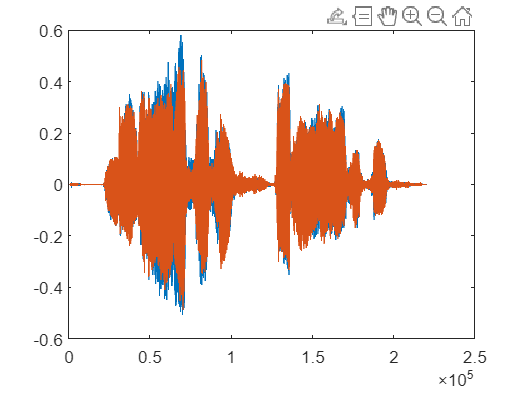

% Gender Recognition from Pre-recorded Audio using Pitch and Energy Thresholds

% Step 1: Record Audio Password and filter the noise
%recorder = audiorecorder(44100, 16, 1); % Adjust settings as needed
%disp('Recording...Ref_Audio');
%recordblocking(recorder, 5); % Record for 5 seconds (adjust as needed)
%disp('Recording finished.'); 
fs=44100;

% Get the recorded audio
%audioData = getaudiodata(recorder);

% Replace 'your_audio_file.wav' with the path to your audio file
audioFile = 'FSample.mp3';

% Read the audio file
[audioData, fs] = audioread(audioFile);
% Play the audio
sound(audioData, 44100);
plot(audioData)


% Extract pitch and energy as features
fundamentalFrequency = pitch(audioData, fs)

fundamentalFrequency =   290.1316  290.1316
  282.6923  284.5161
  282.6923  284.5161
  284.5161  284.5161
  284.5161  286.3636
  286.3636  288.2353
  290.1316  288.2353
  295.9732  292.0530
  315.0000  308.3916
  321.8978  319.5652


energy = sum(audioData.^2)

energy = 1.0e+03 *

    3.3646    3.1776



% Set thresholds for gender classification (you may need to adjust these)
pitchThreshold =260; % Adjust based on your data
energyThreshold = 3; % Adjust based on your data


F=mean(fundamentalFrequency)

F =   270.8557  271.0474


E=mean(energy) 

E = 3.2711e+03


% Classify the voice as male or female
if all(mean(fundamentalFrequency) < pitchThreshold) && all(mean(energy) > energyThreshold)
    disp('Predicted gender: Male');
else
    disp('Predicted gender: FeMale');
end

Predicted gender: FeMale
